%Q1
T = 2; v = 65;
Twc = 13.112 + 0.6215*T - 11.37*(v^0.16) + 0.3965*T*(v^0.16);
fprintf('Wind chill temp = %3.0f deg Celsius ', Twc)

Wind chill temp =  -6 deg Celsius 

%Q2
P = 100000;
r = .0485;
y = 10:15;
M = round(P*(r/12)./(1-(1+ r/12).^(-12*y)));
table = [y' M']

table =           10        1053
          11         979
          12         917
          13         865
          14         821
          15         783


%Q4
h = 8:2:16; V = 1000;
%R1^2 + (1.2*R1)^2 + R1*(1.2R1) = (1 + 1.44 + 1.2)*R1^2 = 3.64*R1^2
term = (V*3)/(3.64*pi)

term = 262.3433

R1 = (term./h).^(1/2)

R1 =     5.7265    5.1219    4.6757    4.3288    4.0493


R2 = 1.2*R1

R2 =     6.8718    6.1463    5.6108    5.1946    4.8591


S = round(pi*(R1 + R2).*sqrt((R2-R1).^2 + h.^2) + pi*(R1.^2 + R2.^2))

S =    571   557   557   563   574


%Q5 %BY INPUT
grades = [81 65 31 78 94 80 65 76 77 95 82 49 75];
l = length(grades);
ave = mean(grades);
stddev = std(grades);
med = median(grades);
fprintf('There are %4.2f grades.\nAverage grade = %4.2f with stddev = %4.2f.\nMedian grade = %4.2f.', l, ave, stddev, med)

There are 13.00 grades.
Average grade = 72.92 with stddev = 17.42.
Median grade = 77.00.

%Q6 
N0 = 1; t = 0:12; k = 0.693;
N = N0.*exp(k*t)

N = 	1.0e+03 *

    0.0010    0.0020    0.0040    0.0080    0.0160    0.0320    0.0639    0.1279    0.2557    0.5113    1.0225    2.0447    4.0888


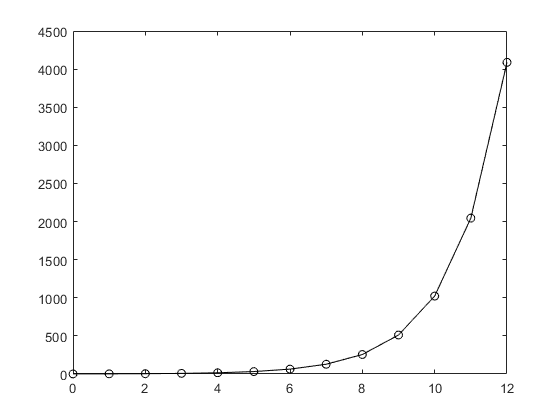

% at t = 12, N = 4,096
% at t = 24, N = 16,777,216
plot(t, N,'-ok')

%9
t = 0:4:48;
k = -(log(2)/13.3)

k = -0.0521

A_48 = 100*exp(k*48)

A_48 = 8.1955

A = 100.*exp(k*t)

A =   100.0000   81.1829   65.9067   53.5050   43.4369   35.2633   28.6278   23.2409   18.8676   15.3173   12.4350   10.0951    8.1955


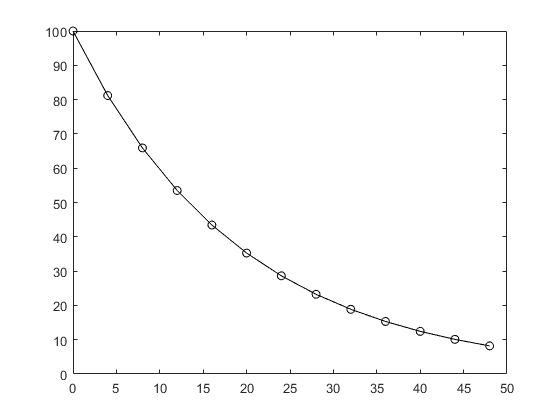

plot(t, A, '-ok')

%Q10 
format bank
A = 10000; r = 2:0.5:6; n = 10;
B = A.*(1+r/100).^n;
table = [r' B']

table =           2.00      12189.94
          2.50      12800.85
          3.00      13439.16
          3.50      14105.99
          4.00      14802.44
          4.50      15529.69
          5.00      16288.95
          5.50      17081.44
          6.00      17908.48


%Q17
alt = -150:150:3000;
p = 29.921*25.4*(1-6.8733e-6.*alt/0.3048)

p =         762.56        759.99        757.42        754.85        752.28        749.71        747.14        744.57        742.00        739.43        736.86        734.29        731.72        729.14        726.57        724.00        721.43        718.86        716.29        713.72        711.15        708.58


Tb = 49.161.*log(p/25.4) + 12.932*(5/9)

Tb =         174.43        174.26        174.09        173.93        173.76        173.59        173.42        173.25        173.08        172.91        172.74        172.57        172.40        172.22        172.05        171.88        171.70        171.53        171.35        171.17        171.00        170.82


%Q18
a = 34172; b = 7.9622; T_c=0:2:42;
T_k = 273+T_c;
p = 10.^(b - (0.05223*a./T_k))

p =          26.57         29.65         33.03         36.73         40.79         45.23         50.09         55.38         61.15         67.43         74.25         81.66         89.69         98.39        107.80        117.97        128.94        140.77        153.51        167.22        181.95        197.77


%Q19
format short
A = [38.91 3.904e-2 -3.105e-5 8.606e-9;
    48.50 9.188e-2 -8.540e-5 32.40e-9;
    29.10 1.158e-2 -0.6076e-5 1.311e-9;
    29.00 0.2199e-2 -0.5723e-5 -2.871e-9];
t = [25 50:50:300];
B = [ones(1, length(t)); t; t.^2; t.^3]

B =            1           1           1           1           1           1           1
          25          50         100         150         200         250         300
         625        2500       10000       22500       40000       62500       90000
       15625      125000     1000000     3375000     8000000    15625000    27000000


Cp = A*B

Cp =    39.8667   40.7855   42.5121   44.0964   45.5448   46.8638   48.0599
   50.7441   52.8845   56.8664   60.4698   63.7192   66.6388   69.2528
   29.3857   29.6640   30.1986   30.7047   31.1834   31.6357   32.0626
   29.0514   29.0953   29.1598   29.1914   29.1879   29.1472   29.0671


table = [t' Cp']

table =    25.0000   39.8667   50.7441   29.3857   29.0514
   50.0000   40.7855   52.8845   29.6640   29.0953
  100.0000   42.5121   56.8664   30.1986   29.1598
  150.0000   44.0964   60.4698   30.7047   29.1914
  200.0000   45.5448   63.7192   31.1834   29.1879
  250.0000   46.8638   66.6388   31.6357   29.1472
  300.0000   48.0599   69.2528   32.0626   29.0671


table2 = [table(1,2:5);table(4,2:5);table(7,2:5); 1 1 1 1]

table2 =    39.8667   50.7441   29.3857   29.0514
   44.0964   60.4698   30.7047   29.1914
   48.0599   69.2528   32.0626   29.0671
    1.0000    1.0000    1.0000    1.0000


Cpm = [39.82; 44.72; 49.10;1]

Cpm =    39.8200
   44.7200
   49.1000
    1.0000


X = table2\Cpm

X =     0.1477
    0.4212
    0.1002
    0.3308


%Q27 
    %a  b  c  d  e  f  g
A = [1  0  0 -1  0  0  0;
     1  0  0  0 -1  0  0;
     0 -1  0  0  0  1  0;
     0 -3  0  0  4  1  1;
     0  0 -1  0  0  0  2;
     0  1 -1  2 -2  0  0;
     3  0  0  0  0  0  0];
B = [0;0;0;0;0;0;3];
X = A\B

X =     1.0000
    2.6667
    2.6667
    1.0000
    1.0000
    2.6667
    1.3333


% TRY S = X/min(X) or multiply X by 1,2,3,...
S = X*3

S =     3.0000
    8.0000
    8.0000
    3.0000
    3.0000
    8.0000
    4.0000


%Q28
T = 5:-5:-35

T =      5     0    -5   -10   -15   -20   -25   -30   -35


v = 15:15:90

v =     15    30    45    60    75    90


Twc = round(13.112 + (0.6215).*T - (11.37)*v'.^0.16 + (0.3965)*T.*v'.^0.16)

Twc =      2    -4   -11   -17   -23   -29   -35   -41   -48
     0    -6   -13   -20   -26   -33   -39   -46   -52
    -1    -8   -15   -21   -28   -35   -42   -48   -55
    -2    -9   -16   -23   -30   -36   -43   -50   -57
    -3   -10   -17   -24   -31   -38   -45   -52   -59
    -3   -10   -17   -25   -32   -39   -46   -53   -61
